# Projekt 5

## Nastavitev parametrov


T = 0.01;

% Definicija parametrov
N = 300;
N_APRBS = 3000;
amplitude_train = 2.5;
amplitude_test = 2.0;
Th = 0.20;
padding = 100;
dV = 0.05;
c = zeros(2 / dV + 1, 1);

## Statična karaktersitika

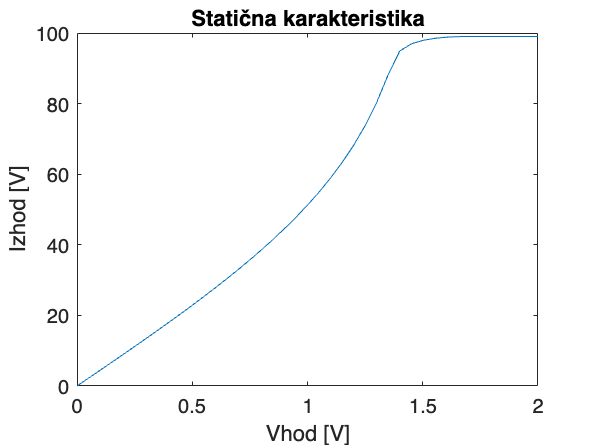

% Zanka za različne vrednosti V
for V = 0:dV:2
    u = ones(N, 1) * V;

    % Inicializacija stanja
    x = [0, 0];

    % Inicializacija izhodnega vektorja
    y = zeros(N, 1);

    % Simulacija helicrana
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u(i), x);

        % Posodobitev stanja
        x = [fip_, fi_];

        % Shranjevanje izhoda
        y(i) = fi_;
    end

    % Izračun povprečja izhodnih vrednosti po prehodnem obdobju
    y_m = mean(y(100:end));

    % Shranjevanje rezultata v c
    c(round(V/dV) + 1) = y_m;
end

% Risanje rezultata
figure;
plot(0:dV:2, c);
title("Statična karakteristika");
xlabel("Vhod [V]");
ylabel("Izhod [V]");

## Generiranje in risanje APRBS signala

% Parametri
N = 1000; % Število vzorcev
Th = 7; % Časovna konstanta
T = 0.1; % Čas vzorčenja
amplitude_train = 1;
amplitude_test = 1;
padding = 100;
N_APRBS = N; % Število APRBS vzorcev

% Generiranje APRBS signala za treniranje
u_train = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

d_train = diff(u_train);
idx_train = find(d_train) + 1;
idx_train = [1; idx_train];
for ii = 1:length(idx_train) - 1
    u_train(idx_train(ii):idx_train(ii + 1) - 1) = amplitude_train * rand;
end
u_train(idx_train(end):end) = amplitude_train * rand;
u_train = [zeros(padding, 1); u_train];
u_train = u_train - 0.5; % Odštejemo 0.5, da premaknemo signal

% Generiranje APRBS signala za testiranje
u_test = idinput(N, 'prbs', [0 1 / (Th / T)], [-1 1]);

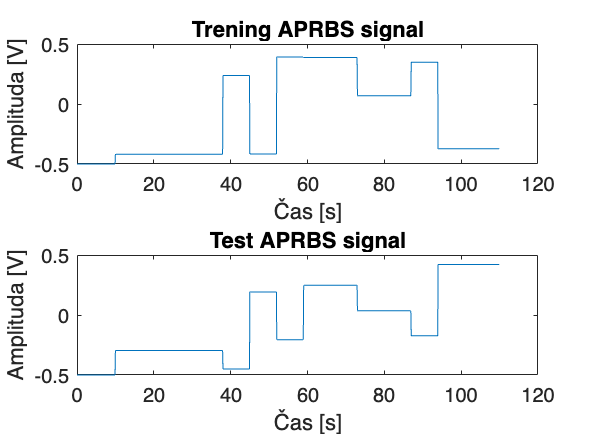

d_test = diff(u_test);
idx_test = find(d_test) + 1;
idx_test = [1; idx_test];
for ii = 1:length(idx_test) - 1
    u_test(idx_test(ii):idx_test(ii + 1) - 1) = amplitude_test * rand;
end
u_test(idx_test(end):end) = amplitude_test * rand;
u_test = [zeros(padding, 1); u_test];
u_test = u_test - 0.5; % Odštejemo 0.5, da premaknemo signal

% Časovni vektorji
t_train = (0:length(u_train)-1) * T;
t_test = (0:length(u_test)-1) * T;

% Risanje rezultatov
figure
subplot(2, 1, 1);
plot(t_train, u_train);
title("Trening APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

subplot(2, 1, 2);
plot(t_test, u_test);
title("Test APRBS signal");
xlabel("Čas [s]");
ylabel("Amplituda [V]");

## odziv sistema na vhodni signal

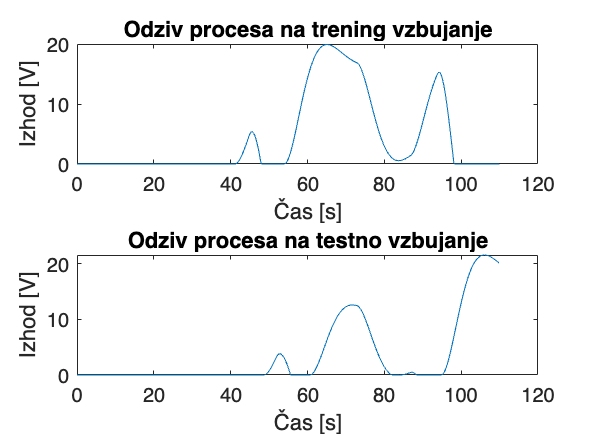


% Simulacija odziva sistema za treniranje in testiranje
y_train = simulate_helicrane(u_train, [0 0]);
y_test = simulate_helicrane(u_test, [0 0]);

% Risanje rezultatov simulacije
figure
subplot(2, 1, 1);
plot(t_train, y_train);
title("Odziv procesa na trening vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");

subplot(2, 1, 2);
plot(t_test, y_test);
title("Odziv procesa na testno vzbujanje");
xlabel("Čas [s]");
ylabel("Izhod [V]");


% Preverjanje dolžine vektorjev u_train in y_train
if length(u_train) > 2 && length(y_train) > 2
    % Priprava vhodnih in izhodnih podatkov za učenje
    X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
    Y_train_podatki = y_train(3:end);

    % Premešanje podatkov za učenje
    perm_indeksi = randperm(size(X_train_podatki, 1));
    X_train_premesani = X_train_podatki(perm_indeksi, :);
    Y_train_premesani = Y_train_podatki(perm_indeksi, :);

    % Priprava vhodnih in izhodnih podatkov za testiranje
    X_test_podatki = [u_test(2:end-1), u_test(1:end-2), -y_test(2:end-1), -y_test(1:end-2)];
    Y_test_podatki = y_test(3:end);

    % Simulacija helicrana brez uporabe funkcije
    % Inicializacija stanja
    zacetno_stanje = [0, 0];

    % Dolžina vhoda
    N = length(u_train); % Tu mora biti dolžina u_train

    % Inicializacija izhoda
    izhodi = zeros(N, 1);

    % Glavna zanka za simulacijo
    for i = 1:N
        % Klic funkcije helicrane
        [fi_, fip_] = helicrane(u_train(i), zacetno_stanje);

        % Posodobitev stanja
        zacetno_stanje = [fip_, fi_];

        % Shranjevanje izhoda
        izhodi(i) = fi_;
    end

    % Prikaz končnih izhodov (izhodi)
    disp(izhodi);
else
    disp('Napaka: u_train ali y_train nimata dovolj elementov.');
end

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0

## nevronska mreža

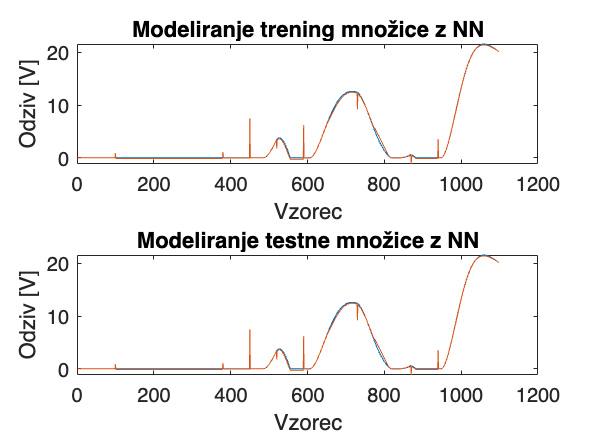



net = feedforwardnet([15, 12, 10]);
net.layers{1}.transferFcn = 'tansig';
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'poslin';
net.trainParam.showWindow = false;
net.trainParam.goal = 2e-6;
[net, ~] = train(net, X_train_podatki', Y_train_podatki');

subplot(2, 1, 1);
plot(Y_test_podatki);
title("Modeliranje trening množice z NN")
hold on;
plot(net(X_test_podatki'));
xlabel("Vzorec")
ylabel("Odziv [V]")

subplot(2, 1, 2);
plot(Y_test_podatki);
title("Modeliranje testne množice z NN")
hold on;
plot(net(X_test_podatki'));
xlabel("Vzorec")
ylabel("Odziv [V]")

## Takagi Sugeno model

% 1) Priprava vhodnih podatkov (X_train) in izhodnih podatkov (Y_train)
X_train_podatki = [u_train(2:end-1), u_train(1:end-2), -y_train(2:end-1), -y_train(1:end-2)];
Y_train_podatki = y_train(3:end);

% 2) pridobivanje centrov lokalnih funkcij s FCM
R = 15; % Število pravil
[centers, U] = fcm(X_train_podatki, R);

Iteration count = 1, obj. fcn = 8409.62
Iteration count = 2, obj. fcn = 6339.62
Iteration count = 3, obj. fcn = 5898.46
Iteration count = 4, obj. fcn = 3972.82
Iteration count = 5, obj. fcn = 1843.91
Iteration count = 6, obj. fcn = 913.709
Iteration count = 7, obj. fcn = 482.47
Iteration count = 8, obj. fcn = 294.914
Iteration count = 9, obj. fcn = 243.031
Iteration count = 10, obj. fcn = 217.406
Iteration count = 11, obj. fcn = 197.302
Iteration count = 12, obj. fcn = 172.84
Iteration count = 13, obj. fcn = 163.588
Iteration count = 14, obj. fcn = 160.795
Iteration count = 15, obj. fcn = 159.229
Iteration count = 16, obj. fcn = 158.042
Iteration count = 17, obj. fcn = 157.017
Iteration count = 18, obj. fcn = 156.069
Iteration count = 19, obj. fcn = 155.163
Iteration count = 20, obj. fcn = 154.285
Iteration count = 21, obj. fcn = 153.435
Iteration count = 22, obj. fcn = 152.619
Iteration count = 23, obj. fcn = 151.848
Iteration count = 24, obj. fcn = 151.131
Iteration count = 25, obj. 

C = centers; % Centri funkcij pripadnosti

% 3) Pripadnost funckije (O), uteži (W), pragovi (b)
O = ones(R, 1) * std(X_train_podatki); % Inicializacija širine funkcij pripadnosti
% Za vsako vvhodno spremenljivko računamo std -> 1 x n
W = rand(R, size(X_train_podatki, 2)) * 2 - 1; % Naključna inicializacija uteži od -1 do 1
b = rand(R, 1) * 2 - 1; % Naključna inicializacija pragov


% 4) trening TS modela
alpha = 0.000002; % Hitrost učenja
epochs = 400; % Število epoh za treniranje
[C, O, W, b, e] = TS_train(C, O, W, b, X_train_podatki', Y_train_podatki', alpha, epochs);

Epoka 100: Povprečna napaka: 944568616936146339488068997795414729031680.000000
Epoka 200: Povprečna napaka: 193523811596072554145565769477336659799064240101583477017607340601142816947542001539088384.000000
Epoka 300: Povprečna napaka: 39649280087403064777893479420225112117116729862494699624730736738786022366995493644335593760374078374802407808869368545456995623206125568.000000
Epoka 400: Povprečna napaka: 8123369411153636983203739057017636356874975409868561433188129000284227695744432026217866746808670120498149614883748296728777890258977790720252442384696319461765461634051209633388822528.000000
Končna povprečna napaka: 8123369411153636983203739057017636356874975409868561433188129000284227695744432026217866746808670120498149614883748296728777890258977790720252442384696319461765461634051209633388822528.000000


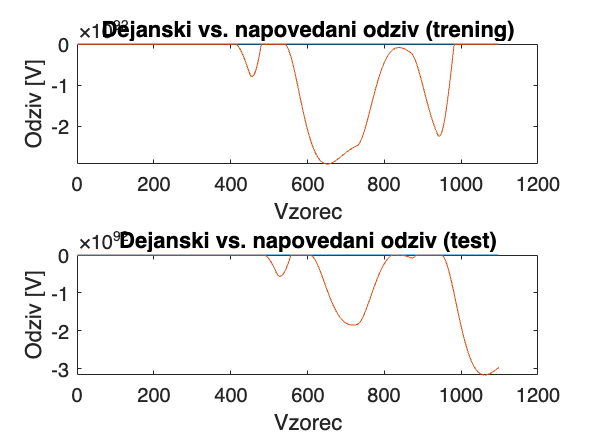

% 5) testiranje na testnih podatkih
Y_pred_train = TS_eval(C, O, W, b, X_train_podatki');
Y_pred_test = TS_eval(C, O, W, b, X_test_podatki');

% Risanje rezultatov
figure;
subplot(2, 1, 1);
plot(Y_train_podatki);
hold on;
plot(Y_pred_train);
title('Dejanski vs. napovedani odziv (trening)');
xlabel('Vzorec');
ylabel('Odziv [V]');

subplot(2, 1, 2);
plot(Y_test_podatki);
hold on;
plot(Y_pred_test);
title('Dejanski vs. napovedani odziv (test)');
xlabel('Vzorec');
ylabel('Odziv [V]');

function [C, O, W, b, e_avg] = TS_train(C, O, W, b, X, Y, alpha, epochs)
    % C - centri (R x n)
    % O - širine funkcij pripadnosti (R x n)
    % W - uteži (R x n)
    % b - pristranskosti (R x 1)
    % X - vhodni podatki (n x m)
    % Y - izhodni podatki (1 x m)
    % alpha - hitrost učenja
    % epochs - število epoh za treniranje
    % e_avg - povprečna napaka na koncu treninga
    
    % Število pravil (R) in število vhodov (n)
    [R, n] = size(C);
    
    % Glavna zanka treniranja
    for epoch = 1:epochs
        e_sum = 0; % Skupna napaka za izračun povprečne napake
        for i = 1:size(X, 2)
            % Izberi en vzorec iz učnega nabora
            x = X(:, i);  % Vhod (n x 1)
            y_true = Y(i);  % Izhod (skalar)
            
            % Izračunaj vrednost pripadnosti za vsak center
            mu = exp(-0.5 * sum((x' - C).^2 ./ (O.^2), 2));  % Pripadnost (R x 1)
            mu_sum = sum(mu);  % Vsota pripadnosti
            if mu_sum > 0
                mu = mu / mu_sum;  % Normalizacija pripadnosti
            end
            
            % Napovedana vrednost
            y_pred = sum(mu .* (W * x + b));
            
            % Izračun napake
            e = y_true - y_pred;
            e_sum = e_sum + e^2;
            
            % Posodobitev parametrov (gradientni spust)
            dmu_dC = (x' - C) ./ (O.^2) .* mu;
            dmu_dO = ((x' - C).^2) ./ (O.^3) .* mu;
            
            dy_dC = dmu_dC .* (W * x + b - sum(mu .* (W * x + b))) ./ mu_sum^2;
            dy_dO = dmu_dO .* (W * x + b - sum(mu .* (W * x + b))) ./ mu_sum^2;
            dy_db = mu;
            dy_dW = mu * x';
            
            C = C + alpha * (-2 * e * dy_dC);
            O = O + alpha * (-2 * e * dy_dO);
            b = b + alpha * (-2 * e * dy_db);
            W = W + alpha * (-2 * e * dy_dW);
        end
        
        % Povprečna napaka na epohu
        e_avg = e_sum / size(X, 2);
        
        % Prikaz napake na vsakih 100 epoh
        if mod(epoch, 100) == 0
            fprintf("Epoka %d: Povprečna napaka: %f\n", epoch, e_avg);
        end
    end
    
    fprintf("Končna povprečna napaka: %f\n", e_avg);
end

function Y_pred = TS_eval(C, O, W, b, X)
    % C - centri (R x n)
    % O - širine funkcij pripadnosti (R x n)
    % W - uteži (R x n)
    % b - pristranskosti (R x 1)
    % X - vhodni podatki (n x m)
    % Y_pred - napovedani izhodni podatki (1 x m)
    
    % Število pravil (R) in število vhodov (n)
    [R, n] = size(C);
    
    % Število podatkovnih točk
    m = size(X, 2);
    
    % Inicializacija izhodnega vektorja
    Y_pred = zeros(1, m);
    
    % Glavna zanka za napovedovanje
    for i = 1:m
        x = X(:, i);  % Trenutni vhod (n x 1)
        
        % Izračun pripadnosti za vsak center
        mu = exp(-0.5 * sum((x' - C).^2 ./ (O.^2), 2));  % Pripadnost (R x 1)
        mu_sum = sum(mu);  % Vsota pripadnosti
        
        if mu_sum > 0
            mu = mu / mu_sum;  % Normalizacija pripadnosti
        end
        
        % Napovedana vrednost
        Y_pred(i) = sum(mu .* (W * x + b));  % Napovedana vrednost (skalar)
    end
end
